# Qcalc

Qcalc permet de calculer automatiquement les paramètres Z, T et g des quadripôles.


$$\left\lbrack \begin{array}{c}
V_1 \\
V_2 
\end{array}\right\rbrack =Z\left\lbrack \begin{array}{c}
I_1 \\
I_2 
\end{array}\right\rbrack$$



$$\left\lbrack \begin{array}{c}
V_1 \\
I_1 
\end{array}\right\rbrack =T\left\lbrack \begin{array}{c}
V_2 \\
-I_2 
\end{array}\right\rbrack$$



$$\left\lbrack \begin{array}{c}
I_1 \\
V_2 
\end{array}\right\rbrack =g\left\lbrack \begin{array}{c}
V_1 \\
I_2 
\end{array}\right\rbrack$$


Qcalc utilise fspice pour effectuer ce calcul, il faut fspice.p dans le dossier de travail.

Après avoir défini le circuit du quadripôle (sans mettre de source de tension sur $V_1$ !), il faut appeler la fonction Qcal en indiquant la netlist, puis les identifiants des noeuds d'entrée et de sortie du quadripôle :

[Z,T,g]=Qcalc(netlist,n1+,n1-,n2+,n2-)

La tension V1 du quadripôle est définie par la différence de potentiel entre le noeud n1+ et n1-.

La tension V2 du quadripôle est définie par la différence de potentiel entre le noeud n2+ et n2-.

## Exemple : 

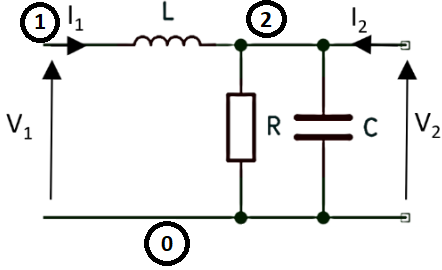

netlist={'L1 1 2 L'
    'C1 2 0 C'
    'R1 2 0 R'};
[Z,T,g]=Qcalc(netlist,'1','0','2','0')

** fspice 2.42  ** (c) Frederic Martinez


netlist = 3×1 cell array
    {'L1 1 2 L'}
    {'C1 2 0 C'}
    {'R1 2 0 R'}


** fspice 2.42  ** (c) Frederic Martinez


netlist = 1×4 cell array
    {'L1 1 2 L'}    {'C1 2 0 C'}    {'R1 2 0 R'}    {'V1$$ 1 0 V1'}


** fspice 2.42  ** (c) Frederic Martinez


netlist = 1×4 cell array
    {'L1 1 2 L'}    {'C1 2 0 C'}    {'R1 2 0 R'}    {'V2$$ 2 0 V2'}


$$Z = \left(\begin{array}{cc} \frac{C\,L\,R\,s^{2}+L\,s+R}{C\,R\,s+1} & \frac{R}{C\,R\,s+1}\\ \frac{R}{C\,R\,s+1} & \frac{R}{C\,R\,s+1} \end{array}\right)$$

$$T = \left(\begin{array}{cc} \frac{C\,L\,R\,s^{2}+L\,s+R}{R} & L\,s\\ \frac{C\,R\,s+1}{R} & 1 \end{array}\right)$$

$$g = \left(\begin{array}{cc} \frac{C\,R\,s+1}{C\,L\,R\,s^{2}+L\,s+R} & -1\\ \frac{R}{C\,L\,R\,s^{2}+L\,s+R} & \frac{L\,R\,s}{C\,L\,R\,s^{2}+L\,s+R} \end{array}\right)$$